# DK e IK SCARA

clc
clear all
close all
addpath('/home/laura/Documents/MATLAB/')


Definición de Parámetros 

% Medidas en cm
d1 = 225; 
d2 = 175; 
d3 = 163.6; 
d4 = 0; 
d5 = -50; 
d6 = 73; 

aij = [0 d1 d2 0 0 0]; 
alphaij = [0 0 pi 0 0 0];
sj = [d3 d4 d5 0 d6 0]; 
thetaj = [0 0 0 0 0 0];
DH = [aij', alphaij', sj', deg2rad(thetaj)']

DH =          0         0  163.6000         0
  225.0000         0         0         0
  175.0000    3.1416  -50.0000         0
         0         0         0         0
         0         0   73.0000         0
         0         0         0         0



frame=size(DH,1);

#### Transformada DH

for i=1:frame
    T_ij(:,:,i)=T_DH(DH(i,1),DH(i,2),DH(i,3),DH(i,4)); %Saca todos los frames respecto a un marco local
end
T(:,:,1)=T_ij(:,:,1);
for i=1:frame-1
    T(:,:,i+1)=T(:,:,i)*T_ij(:,:,i+1); % Transformacones de traslación y rotación (premult)
end
T

T = T(:,:,1) =

    1.0000         0         0         0
         0    1.0000         0         0
         0         0    1.0000  163.6000
         0         0         0    1.0000


T(:,:,2) =

    1.0000         0         0  225.0000
         0    1.0000         0         0
         0         0    1.0000  163.6000
         0         0         0    1.0000


T(:,:,3) =

    1.0000         0         0  400.0000
         0   -1.0000   -0.0000    0.0000
         0    0.0000   -1.0000  213.6000
         0         0         0    1.0000


T(:,:,4) =

    1.0000         0         0  400.0000
         0   -1.0000   -0.0000    0.0000
         0    0.0000   -1.0000  213.6000
         0         0         0    1.0000


T(:,:,5) =

    1.0000         0         0  400.0000
         0   -1.0000   -0.0000   -0.0000
         0    0.0000   -1.0000  140.6000
         0         0         0    1.0000


T(:,:,6) =

    1.0000         0         0  400.0000
         0   -1.0000   -0.0000   -0.0000
         0  

#### Gráfica

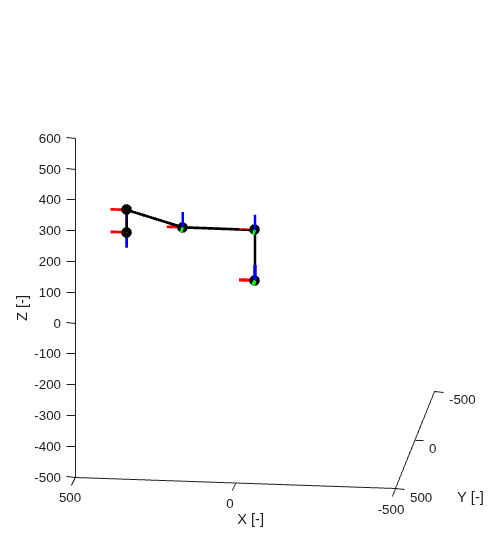

% Define the Fixed Frame
hf=figure(1);
set(hf,'position',[445   275   563   628])
% Unit vectors scale factor(visual)
L=50;
h_ejexF=plot3([0 L],[0 0],[0 0],'r','linewidth',2.5);
hold on
h_ejeyF=plot3([0 0],[0 L],[0 0],'g','linewidth',2.5);
hold on
h_ejezF=plot3([0 0],[0 0],[0 L],'b','linewidth',2.5);
hold on
axis equal
axis([-500 500 -500 500 -500 600])
xlabel('X [-]')
ylabel('Y [-]')
zlabel('Z [-]')
view(-27,-37)
% Mobile Coordinate System Based on DoF
for i=1:frame
    h_ejexM(i,1)=plot3([0 0],[0 0],[0 0],'r','linewidth',2);
    hold on
    h_ejeyM(i,1)=plot3([0 0],[0 0],[0 0],'g','linewidth',2);
    hold on
    h_ejezM(i,1)=plot3([0 0],[0 0],[0 0],'b','linewidth',2);
end
% Points Matrix on {j}
Mp=[0,0,0,1;
    L,0,0,1;
    0,L,0,1;
    0,0,L,1];
% Points Matrix on {0}
for k=1:frame
    for i=1:4
        Mp_T(i,:,k)=(T(:,:,k)*Mp(i,:)')'; % MARCO GLOBAL
    end
end
% Plot each Coordinate System in the Global Frame
for k=1:frame
    set(h_ejexM(k,1),'xdata',[Mp_T(1,1,k) Mp_T(2,1,k)],...
        'ydata',[Mp_T(1,2,k) Mp_T(2,2,k)],...
        'zdata',[Mp_T(1,3,k) Mp_T(2,3,k)])
    set(h_ejeyM(k,1),'xdata',[Mp_T(1,1,k) Mp_T(3,1,k)],...
        'ydata',[Mp_T(1,2,k) Mp_T(3,2,k)],...
        'zdata',[Mp_T(1,3,k) Mp_T(3,3,k)])
    set(h_ejezM(k,1),'xdata',[Mp_T(1,1,k) Mp_T(4,1,k)],...
        'ydata',[Mp_T(1,2,k) Mp_T(4,2,k)],...
        'zdata',[Mp_T(1,3,k) Mp_T(4,3,k)])
end

% Extract Origins: [Base (0,0,0) -> Frame 1 -> Frame 2 -> ...]
P = [0 0 0; squeeze(T(1:3,4,:))']; 

% GRaph the links
plot3(P(:,1), P(:,2), P(:,3), 'k-o', 'LineWidth', 2, 'MarkerFaceColor', 'k');